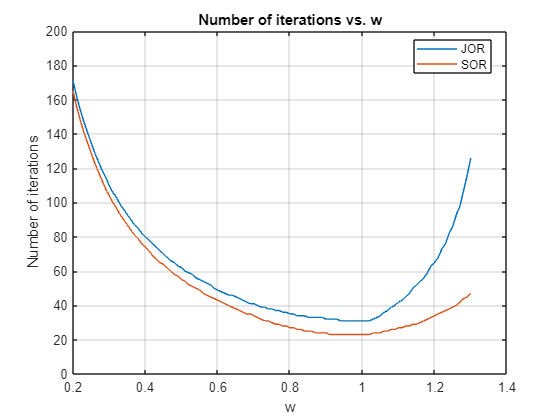

% Define the range of w values
w = 0.2:0.01:1.3;

% Initialize an array to store the number of iterations for each w
iterations_jor = zeros(size(w));
iterations_sor = zeros(size(w));

% Define the matrix A and vector b
A = [-28 0 2 -1 3 0 7 4 0 -8;
    0 41 0 13 7 4 -3 1 -3 -2;
    -2 13 -76 1 0 12 4 2 1 6;
    1 3 -4 37 9 -7 2 8 0 0;
    2 6 -3 0 29 1 9 -5 0 1;
    0 -2 1 0 3 113 -15 0 4 0;
    23 0 -7 3 0 10 -218 46 -2 3;
    -17 18 1 -2 1 0 0 60 9 11;
    281 13 -1 -28 0 -13 2 -301 -645 -4;
    1 0 47 402 -331 84 -52 18 23 961];

b = [31; -17; 22; 32; 24; -377; -673; -55; -943; -5213];

% Define the maximum number of iterations
K = 200;

% Perform JOR iterations for each w value
for i = 1:numel(w)
    % Call the JOR function to get the number of iterations for the current w value
    iterations_jor(i) = JOR(A, b, w(i), K);
end

% Perform SOR iterations for each w value
for i = 1:numel(w)
    % Call the SOR function to get the number of iterations for the current w value
    iterations_sor(i) = SOR(A, b, w(i), K);
end

% Plot the results
plot(w, iterations_jor, 'DisplayName', 'JOR');
hold on;
plot(w, iterations_sor, 'DisplayName', 'SOR');
hold off;
xlabel('w');
ylim([0, K])
ylabel('Number of iterations');
title('Number of iterations vs. w');
grid on;
legend('Location', 'best');